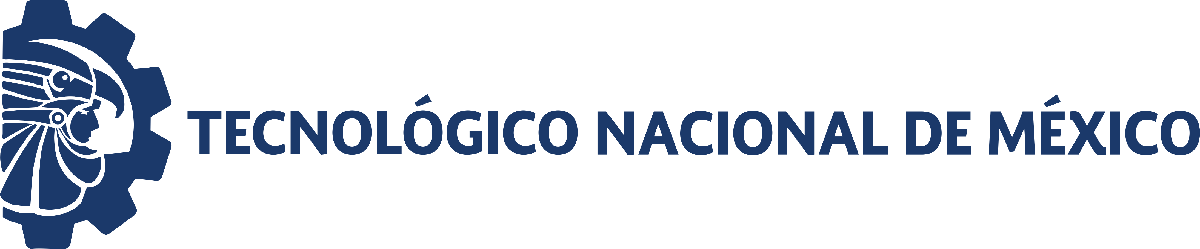                                 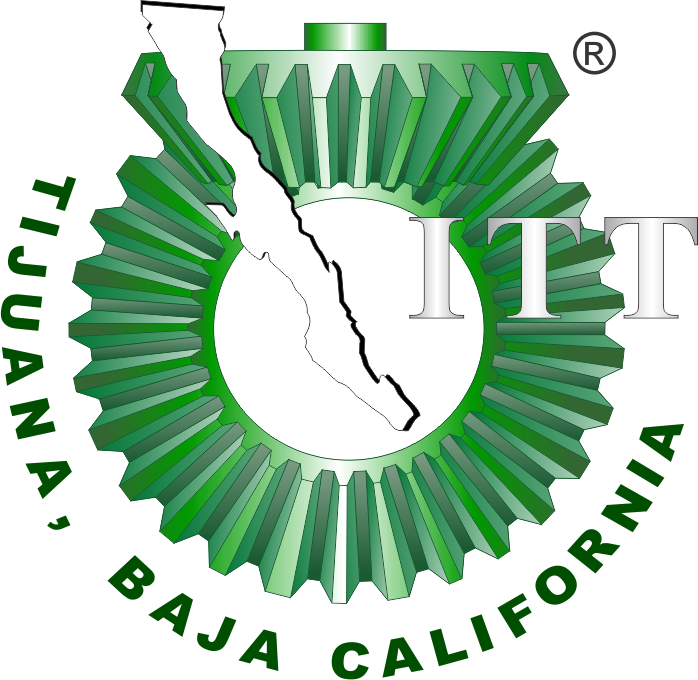

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

# Práctica 1: Sistema presa-depredador de Lotka-Volterra

**Objetivo. ** Aplicar el sistema de Lotka-Volterra para analizar los datos registrados en la interacción de dos especies articas, liebres (presa) y linces (depredador) durante 20 años. El sistema presa-depredador se formula mediante las siguientes dos EDOs de primer orden:


$$\dot x = \alpha x - \beta xy
$$



$$\dot y = \delta xy - \gamma y$$


donde los valores de los parámetros $\alpha$,$\beta ,$$\delta ,$$\gamma >0$, y las condiciones iniciales $x\left(0\right),$$y\left(0\right)>0$.

***[Figura representativa del sistema elaborada en BioRender] ***

Figura. Generar la figura del sistema presa-depredador con [https://bioart.niaid.nih.gov/](https://bioart.niaid.nih.gov/) o [https://www.biorender.com/](https://www.biorender.com/).

## Referencias

[1] Valle, Paul A., Syllabus para Biología de Sistemas y Gemelos Digitales, Tecnológico Nacional de México / Instituto Tecnológico de Tijuana, Tijuana, B.C., México, 2026. Permalink: [https://biomath.xyz/course/](https://biomath.xyz/course/) 

[2] Garfinkel, Alan, Jane Shevtsov, and Yina Guo. Modeling life: the mathematics of biological systems. Springer International Publishing AG, 2017.

## Información general

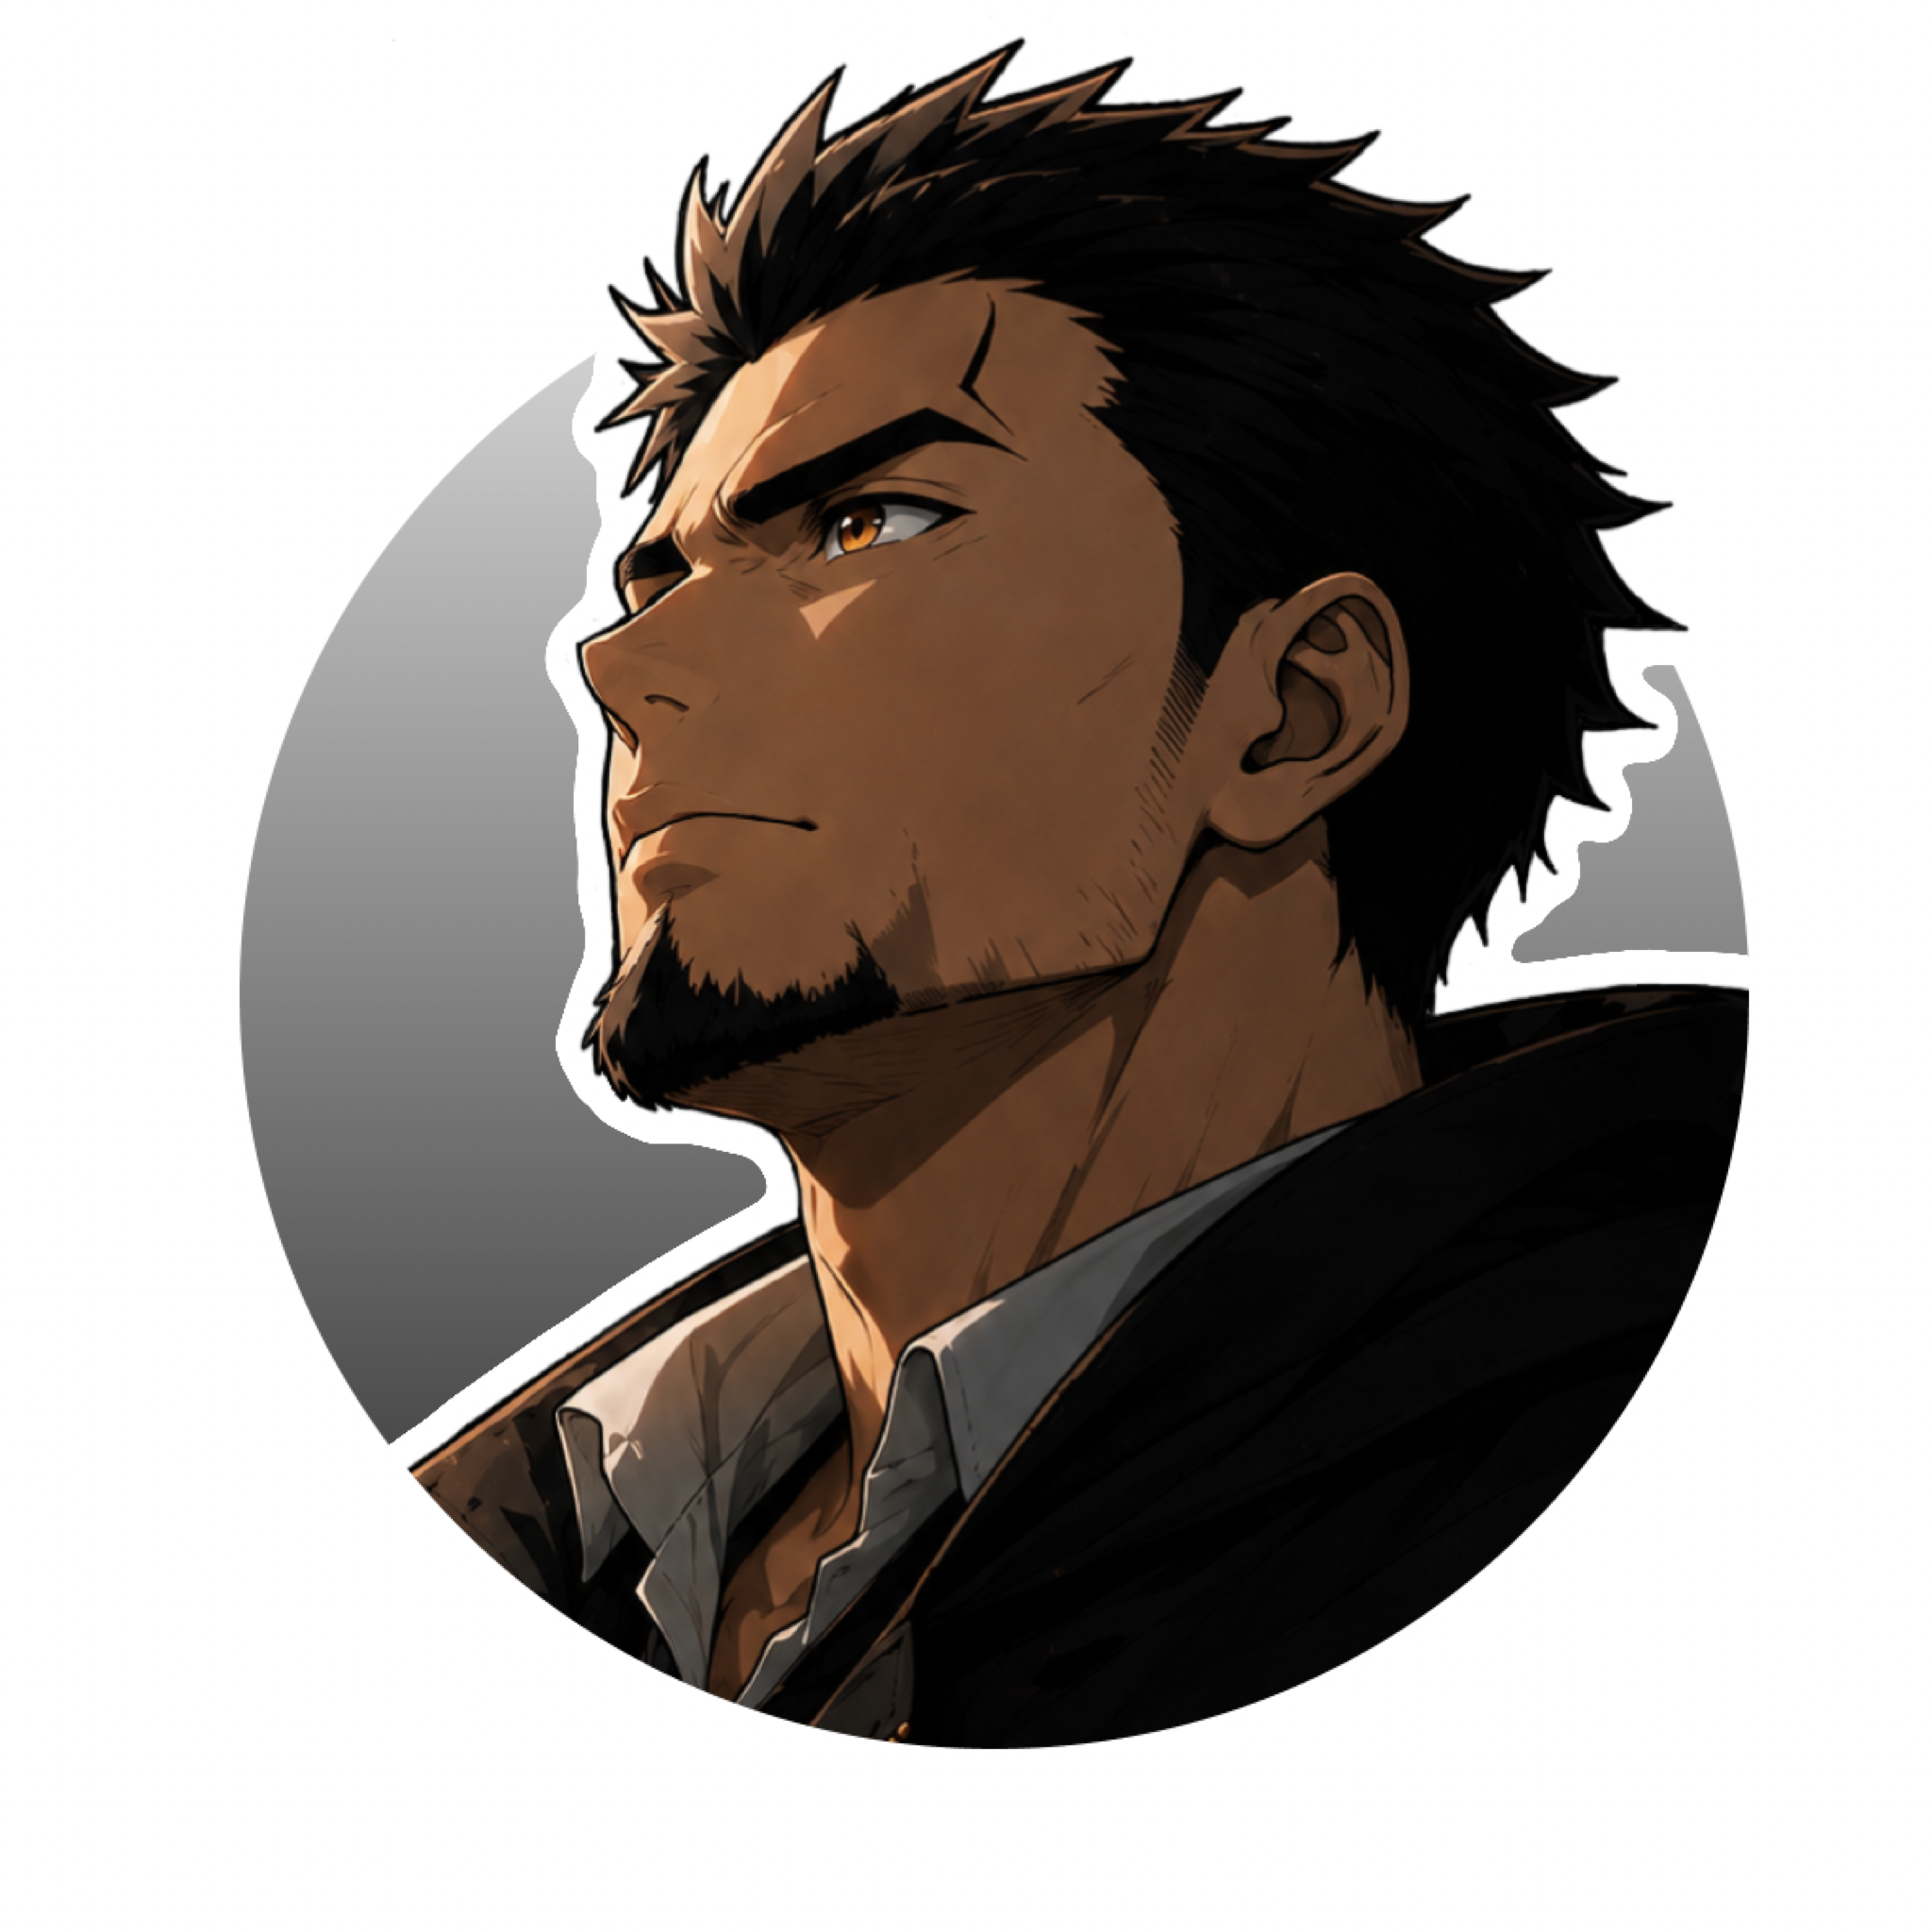

***[Foto 250x250]***

Nombre del alumno: **Nombres y Apellidos**

Número de control: **12345678**

Correo institucional: **xxx.xxx@tectijuana.edu.mx**

Asignatura: **Modelado Matemático**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos experimentales

clc; clear; close all; warning('off','all')

## Datos crudos

file = 'data.csv'; smooth = false; normalize = false;
[t,x,y] = getdata(file, smooth, normalize); figname = 'data_raw';
plotsys(t,x,y,figname,normalize)
mdl = fitmodel(t,x,y,[0.5;2/max(y);2/max(x);1],true);


-----Biostadísticos-----
Cantidad de datos: 42
Cantidad de parámetros: 4
Grados de libertad: 38
Valor t-student: 2.024
Valor de significancia (alfa) para los intervalos de confianza: 0.050
Relación n/k<40 para el cálculo del AICc: 10.500 
    Parameters      Estimate         SE           MoE                  CI95                Pvalue  
    ___________    __________    __________    __________    ________________________    __________

    {["alpha"]}        0.5591      0.023448      0.047468       0.51163       0.60657    1.8367e-24
    {["beta" ]}    2.8648e-06    1.7032e-07     3.448e-07      2.52e-06    3.2096e-06    3.3861e-19
    {["delta"]}     2.588e-06    1.1245e-07    2.2764e-07    2.3604e-06    2.8157e-06    6.4722e-24
    {["gamma"]}       0.81977      0.036589       0.074

par = table2array(mdl.Coefficients(:,1));
alpha = par(1); beta = par(2); delta = par(3); gamma = par(4);
save('parameters.mat','alpha','beta','delta','gamma');
[ta,xa,ya] = LotkaVolterra(par,t,x(1),y(1));
figname = 'data_raw_fit';
plotfitting(t,x,y,ta,xa,ya,figname,normalize)

## Datos suavizados

file = 'data.csv'; smooth = true; normalize = false;
[t,x,y] = getdata(file, smooth, normalize); figname = 'data_smooth';
plotsys(t,x,y,figname,normalize)
mdl = fitmodel(t,x,y,[0.5,1/max(y),2/max(x),1],true);


-----Biostadísticos-----
Cantidad de datos: 42
Cantidad de parámetros: 4
Grados de libertad: 38
Valor t-student: 2.024
Valor de significancia (alfa) para los intervalos de confianza: 0.050
Relación n/k<40 para el cálculo del AICc: 10.500 
    Parameters      Estimate         SE           MoE                  CI95                Pvalue  
    ___________    __________    __________    __________    ________________________    __________

    {["alpha"]}       0.40533       0.01992      0.040327         0.365       0.44565     4.958e-22
    {["beta" ]}    2.2123e-06    1.3499e-07    2.7326e-07    1.9391e-06    2.4856e-06    8.0747e-19
    {["delta"]}    2.8639e-06    1.3447e-07    2.7221e-07    2.5917e-06    3.1361e-06    1.0015e-22
    {["gamma"]}       0.98698      0.048531      0.0982

par = table2array(mdl.Coefficients(:,1));
[ta,xa,ya] = LotkaVolterra(par,t,x(1),y(1));
figname = 'data_smooth_fit';
plotfitting(t,x,y,ta,xa,ya,figname,normalize)

## Datos normalizados

file = 'data.csv'; smooth = false; normalize = true;
[t,x,y] = getdata(file, smooth, normalize); figname = 'data_norm';
plotsys(t,x,y,figname,normalize)
mdl = fitmodel(t,x,y,[1;1;1;1],true);


-----Biostadísticos-----
Cantidad de datos: 42
Cantidad de parámetros: 4
Grados de libertad: 38
Valor t-student: 2.024
Valor de significancia (alfa) para los intervalos de confianza: 0.050
Relación n/k<40 para el cálculo del AICc: 10.500 
    Parameters     Estimate       SE         MoE              CI95             Pvalue  
    ___________    ________    ________    ________    __________________    __________

    {["alpha"]}    0.56938     0.025642     0.05191    0.51747    0.62129    2.3052e-23
    {["beta" ]}     1.7178     0.099742     0.20192     1.5159     1.9198    1.5247e-19
    {["delta"]}     1.9629     0.091155     0.18453     1.7784     2.1474    6.8042e-23
    {["gamma"]}    0.80236     0.037413    0.075739    0.72662     0.8781    7.8569e-23


-----Criterios de bondad 

par = table2array(mdl.Coefficients(:,1));
[ta,xa,ya] = LotkaVolterra(par,t,x(1),y(1));
figname = 'data_norm_fit';
plotfitting(t,x,y,ta,xa,ya,figname,normalize)

## Desnormalización de los parámetros

file = 'data.csv'; smooth = false; normalize = false;
[t,x,y] = getdata(file, smooth, normalize);
par(2) = par(2)/max(y);
par(3) = par(3)/max(x);
fprintf('alpha: %.3e, beta: %.3e, delta: %.3e, gamma: %.3e',par(1),par(2),par(3),par(4))

alpha: 5.694e-01, beta: 2.915e-06, delta: 2.569e-06, gamma: 8.024e-01

[ta,xa,ya] = LotkaVolterra(par,t,x(1),y(1));
figname = 'data_norm_fit';
plotfitting(t,x,y,ta,xa,ya,figname,normalize)

## Datos suavizados y normalizados

file = 'data.csv'; smooth = true; normalize = true;
[t,x,y] = getdata(file, smooth, normalize); figname = 'data_smoothnorm';
plotsys(t,x,y,figname,normalize)
mdl = fitmodel(t,x,y,[1;1;1;1],true);


-----Biostadísticos-----
Cantidad de datos: 42
Cantidad de parámetros: 4
Grados de libertad: 38
Valor t-student: 2.024
Valor de significancia (alfa) para los intervalos de confianza: 0.050
Relación n/k<40 para el cálculo del AICc: 10.500 
    Parameters     Estimate       SE         MoE              CI95             Pvalue  
    ___________    ________    ________    ________    __________________    __________

    {["alpha"]}    0.40822      0.02322    0.047007    0.36121    0.45523    7.6026e-20
    {["beta" ]}    0.96504     0.061866     0.12524    0.83979     1.0903    4.1682e-18
    {["delta"]}     1.7883     0.096249     0.19485     1.5935     1.9832    1.1503e-20
    {["gamma"]}    0.98375     0.055124     0.11159    0.87216     1.0953    4.5654e-20


-----Criterios de bondad 

par = table2array(mdl.Coefficients(:,1));
[ta,xa,ya] = LotkaVolterra(par,t,x(1),y(1));
figname = 'data_smoothnorm_fit';
plotfitting(t,x,y,ta,xa,ya,figname,normalize)

## Soluciones y plano de fase

clc; clear; close all; warning('off','all')
load('parameters.mat')
file = 'data.csv'; smooth = false; normalize = false;
[~,x,y] = getdata(file, smooth, normalize);
tend = 50;
[ta,xa,ya] = LotkaVolterra([alpha,beta,delta,gamma],tend,x(1),y(1));
figname = 'phase_plane';
plotphase(ta,xa,ya,figname)

## Modelos de EDOs con simulink

clc; clear; close all; warning('off','all')
load('parameters.mat')
file = 'data.csv'; smooth = false; normalize = false;
[~,x,y] = getdata(file, smooth, normalize);
x0 = x(1); y0 = y(1);
filesim = 'sistema';
sim(filesim)
parameters.StopTime = '40';
set_param('sistema/alpha','Value',num2str(alpha))
set_param('sistema/beta','Value',num2str(beta))
set_param('sistema/delta','Value',num2str(delta))
set_param('sistema/gamma','Value',num2str(gamma))
set_param('sistema/x0','Value',num2str(x0))
set_param('sistema/y0','Value',num2str(y0))


## Funciones ode para ecuaciones diff

Funciones ode15s

parameters.Solver = 'ode15s';
f = sim(filesim,parameters);
figname = 'simulink_ode15s';
plotphase(f.t,f.x,f.y,figname)

Funciones ode23s

parameters.Solver = 'ode23s';
f = sim(filesim,parameters);
figname = 'simulink_ode23s';
plotphase(f.t,f.x,f.y,figname)

Funciones ode23t

parameters.Solver = 'ode23t';
f = sim(filesim,parameters);
figname = 'simulink_ode23t';
plotphase(f.t,f.x,f.y,figname)

Funciones ode23tb

parameters.Solver = 'ode23tb';
f = sim(filesim,parameters);
figname = 'simulink_ode23tb';
plotphase(f.t,f.x,f.y,figname)

## Funciones ode para ecuaciones nonstiff

Funciones ode45

parameters.Solver = 'ode45';
f = sim(filesim,parameters);
figname = 'simulink_ode45';
plotphase(f.t,f.x,f.y,figname)

Funciones ode23

parameters.Solver = 'ode23';
f = sim(filesim,parameters);
figname = 'simulink_ode23';
plotphase(f.t,f.x,f.y,figname)

Funciones ode113

parameters.Solver = 'ode113';
f = sim(filesim,parameters);
figname = 'simulink_ode113';
plotphase(f.t,f.x,f.y,figname)

## Funciones ode con paso de integracion fija [diferencias finitas]

parameters.FixedStep = '1E-1';

Funciones ode1

parameters.Solver = 'ode1';
f = sim(filesim,parameters);
figname = 'simulink_ode1';
plotphase(f.t,f.x,f.y,figname)

Funciones ode2

parameters.Solver = 'ode2';
f = sim(filesim,parameters);
figname = 'simulink_ode2';
plotphase(f.t,f.x,f.y,figname)

Funciones ode3

parameters.Solver = 'ode3';
f = sim(filesim,parameters);
figname = 'simulink_ode3';
plotphase(f.t,f.x,f.y,figname)

Funciones ode4

parameters.Solver = 'ode4';
f = sim(filesim,parameters);
figname = 'simulink_ode4';
plotphase(f.t,f.x,f.y,figname)

Funciones ode5

parameters.Solver = 'ode5';
f = sim(filesim,parameters);
figname = 'simulink_ode5';
plotphase(f.t,f.x,f.y,figname)

## Funcion ode seleccionada: ode23tb

parameters.MaxStep = '0.1';
parameters.Solver = 'ode23tb';
f = sim(filesim,parameters);
figname = 'simulink_ode23tb_dt';
plotphase(f.t,f.x,f.y,figname)

## Funciones anonimas

clc; clear; close all; warning('off','all')
load('parameters.mat')
file = 'data.csv'; smooth = false; normalize = false;
[~,x,y] = getdata(file, smooth, normalize);
x0 = x(1); y0 = y(1);
par = [alpha, beta, delta, gamma];

Función ode78

[t,fsol] = ode78(@(t,V) sysODE(V,par),[0,40],[x0,y0]);
x = fsol(:,1);
y = fsol(:,2);
figname = 'simulink_ode78';
plotphase(t,x,y,figname)

Función con arreglo predefinido del tiempo

tspan = (0:1E-3:40)';
[t,fsol] = ode78(@(t,V) sysODE(V,par),tspan,[x0,y0]);
x = fsol(:,1);
y = fsol(:,2);
figname = 'funcion_ode78_dt';
plotphase(t,x,y,figname)

Función ode89

[t,fsol] = ode89(@(t,V) sysODE(V,par),[0,40],[x0,y0]);
x = fsol(:,1);
y = fsol(:,2);
figname = 'simulink_ode89';
plotphase(t,x,y,figname)

Función con arreglo predefinido del tiempo

tspan = (0:1E-3:40)';
[t,fsol] = ode89(@(t,V) sysODE(V,par),tspan,[x0,y0]);
x = fsol(:,1);
y = fsol(:,2);
figname = 'funcion_ode89_dt';
plotphase(t,x,y,figname)

Modelo matemático

function dV = sysODE(V,par) %V(1) = x; V(2) = y
    alpha = par(1); beta = par(2); delta = par(3); gamma = par(4);
    dV = zeros(2,1);
    dV(1) = alpha*V(1) - beta*V(1)*V(2);
    dV(2) = delta*V(1)*V(2) - gamma*V(2);
end

## Estabilidad de los equilibrios

clc; clear; close all; warning('off','all')
load('parameters.mat')
clr3 = [139, 38, 38]/255;

## **Condiciones iniciales: origen**

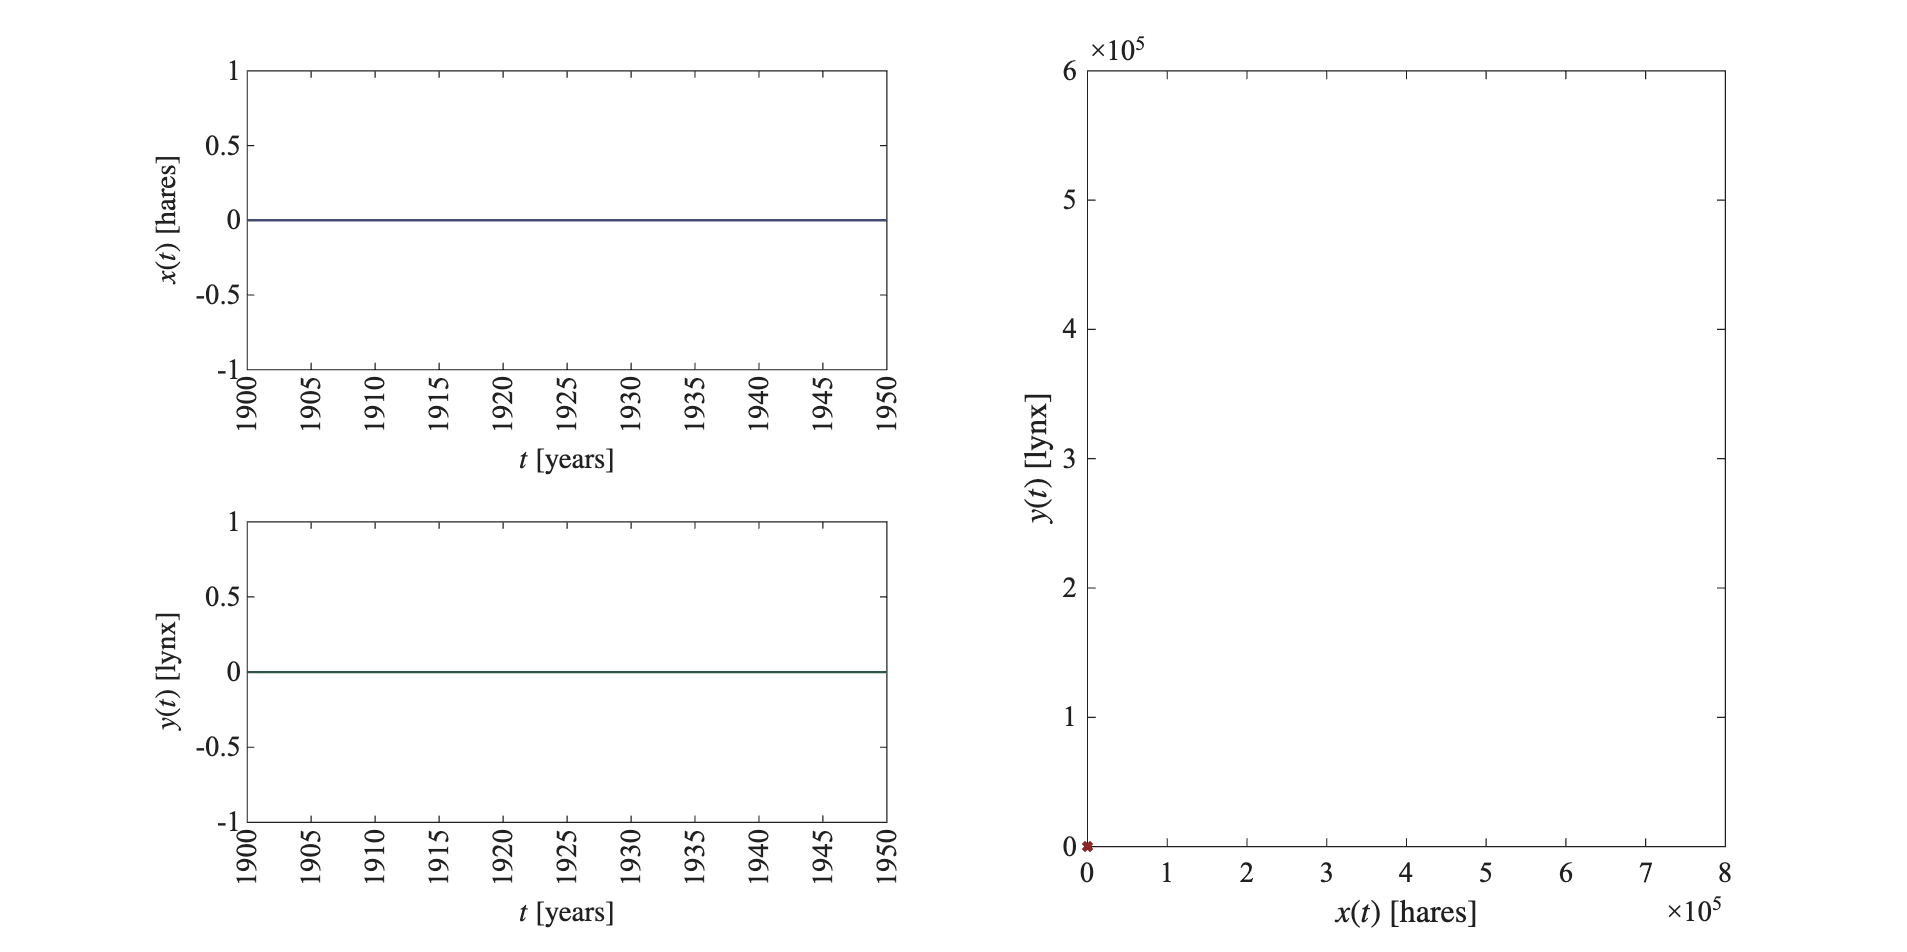

xe0 = 0; ye0 = 0;
tend = 50;
[t,x,y] = LotkaVolterra([alpha,beta,delta,gamma],tend,xe0,ye0);
figname = 'eq_origin';
plotphase(t,x,y,figname);...
    subplot(2,2,1); ylim([-1 1]); yticks(-1:0.5:1);...
    subplot(2,2,3); ylim([-1 1]); yticks(-1:0.5:1);...
    subplot(2,2,[2 4]); plot(xe0,ye0,'x','linewidth',2,'MarkerSize',5,'Color',clr3)

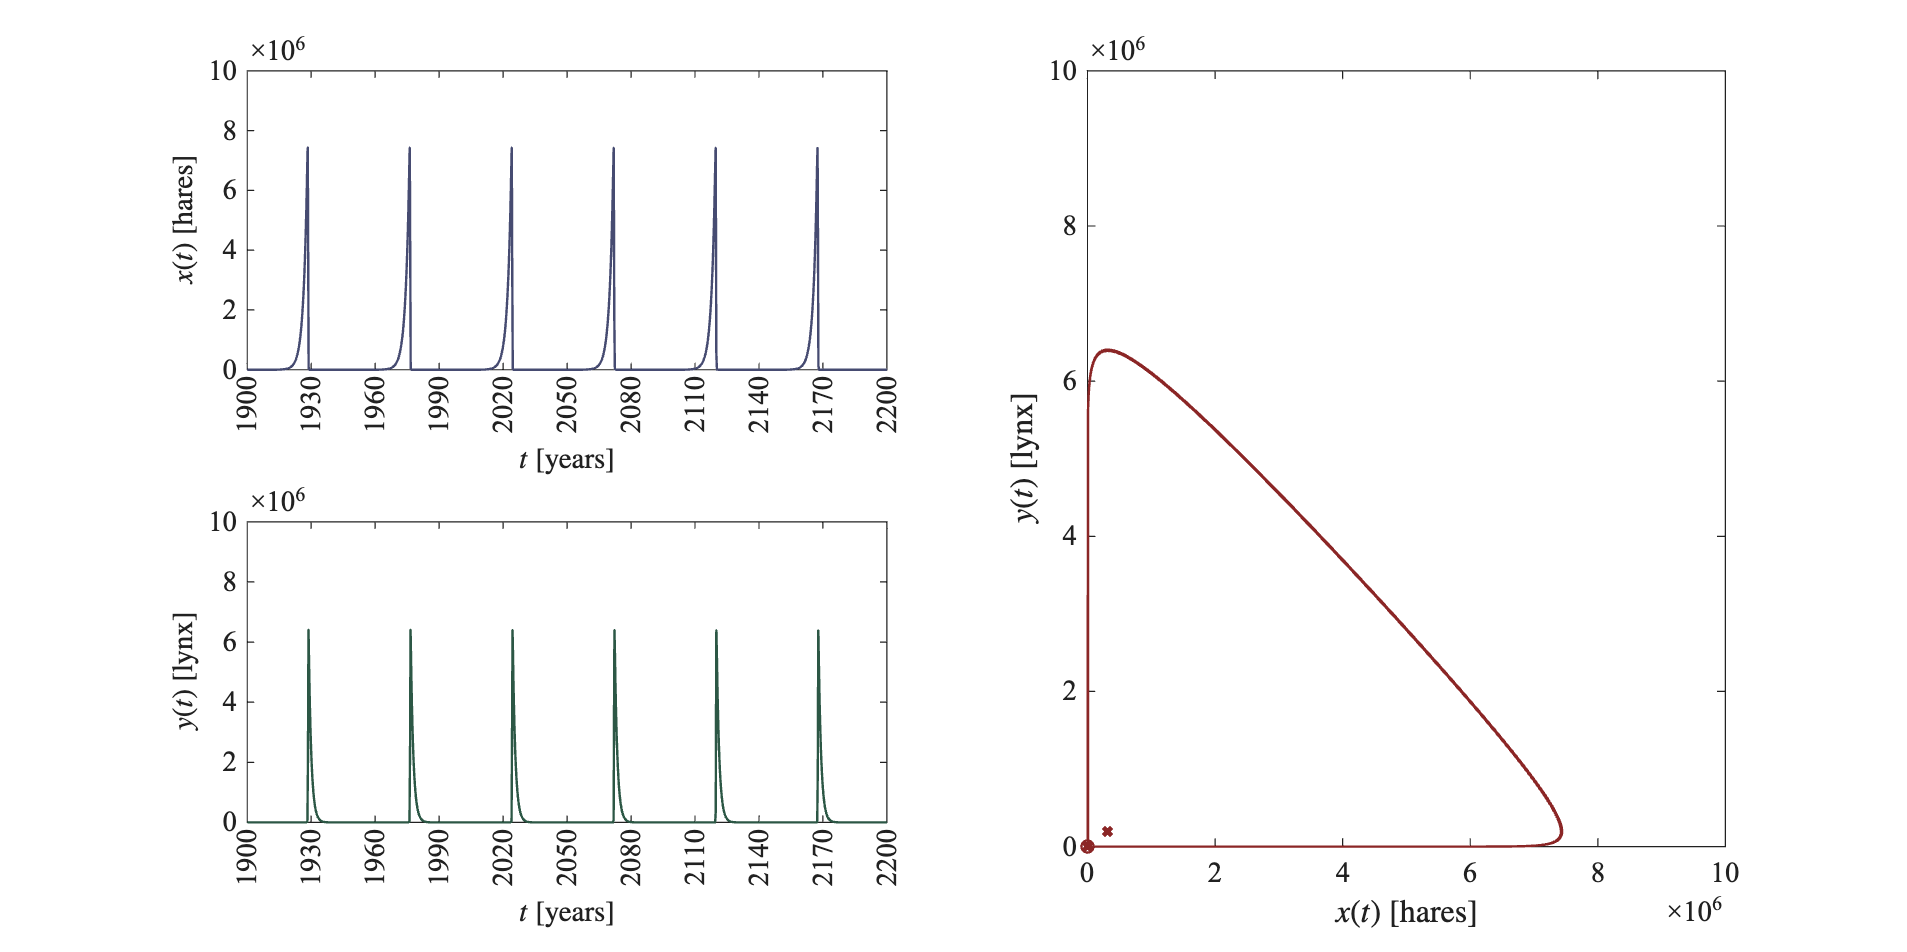

tend = 300;
xe0 = 0; ye0 = 0;
xe1 = gamma/delta; ye1 = alpha/beta;
[t,x,y] = LotkaVolterra([alpha,beta,delta,gamma],tend,1,1);
figname = 'eq_origin_1-1';
plotphase(t,x,y,figname);...
    subplot(2,2,1); ylim([0 1E7]); yticks(0:0.2E7:1E7);...
    subplot(2,2,3); ylim([-1 1E7]); yticks(0:0.2E7:1E7);...
    subplot(2,2,[2 4]); xlim([0 1E7]); xticks(0:0.2E7:1E7); ylim([0 1E7]); yticks(0:0.2E7:1E7);...
    subplot(2,2,[2 4]); plot(xe0,ye0,'x','linewidth',2,'MarkerSize',5,'Color',clr3);...
    subplot(2,2,[2 4]); plot(xe1,ye1,'x','linewidth',2,'MarkerSize',5,'Color',clr3);...
    subplot(2,2,[2 4]); plot(1,1,'o','linewidth',1,'MarkerSize',5,'Color',clr3)

## Condiciones iniciales: Equilibrio de especies

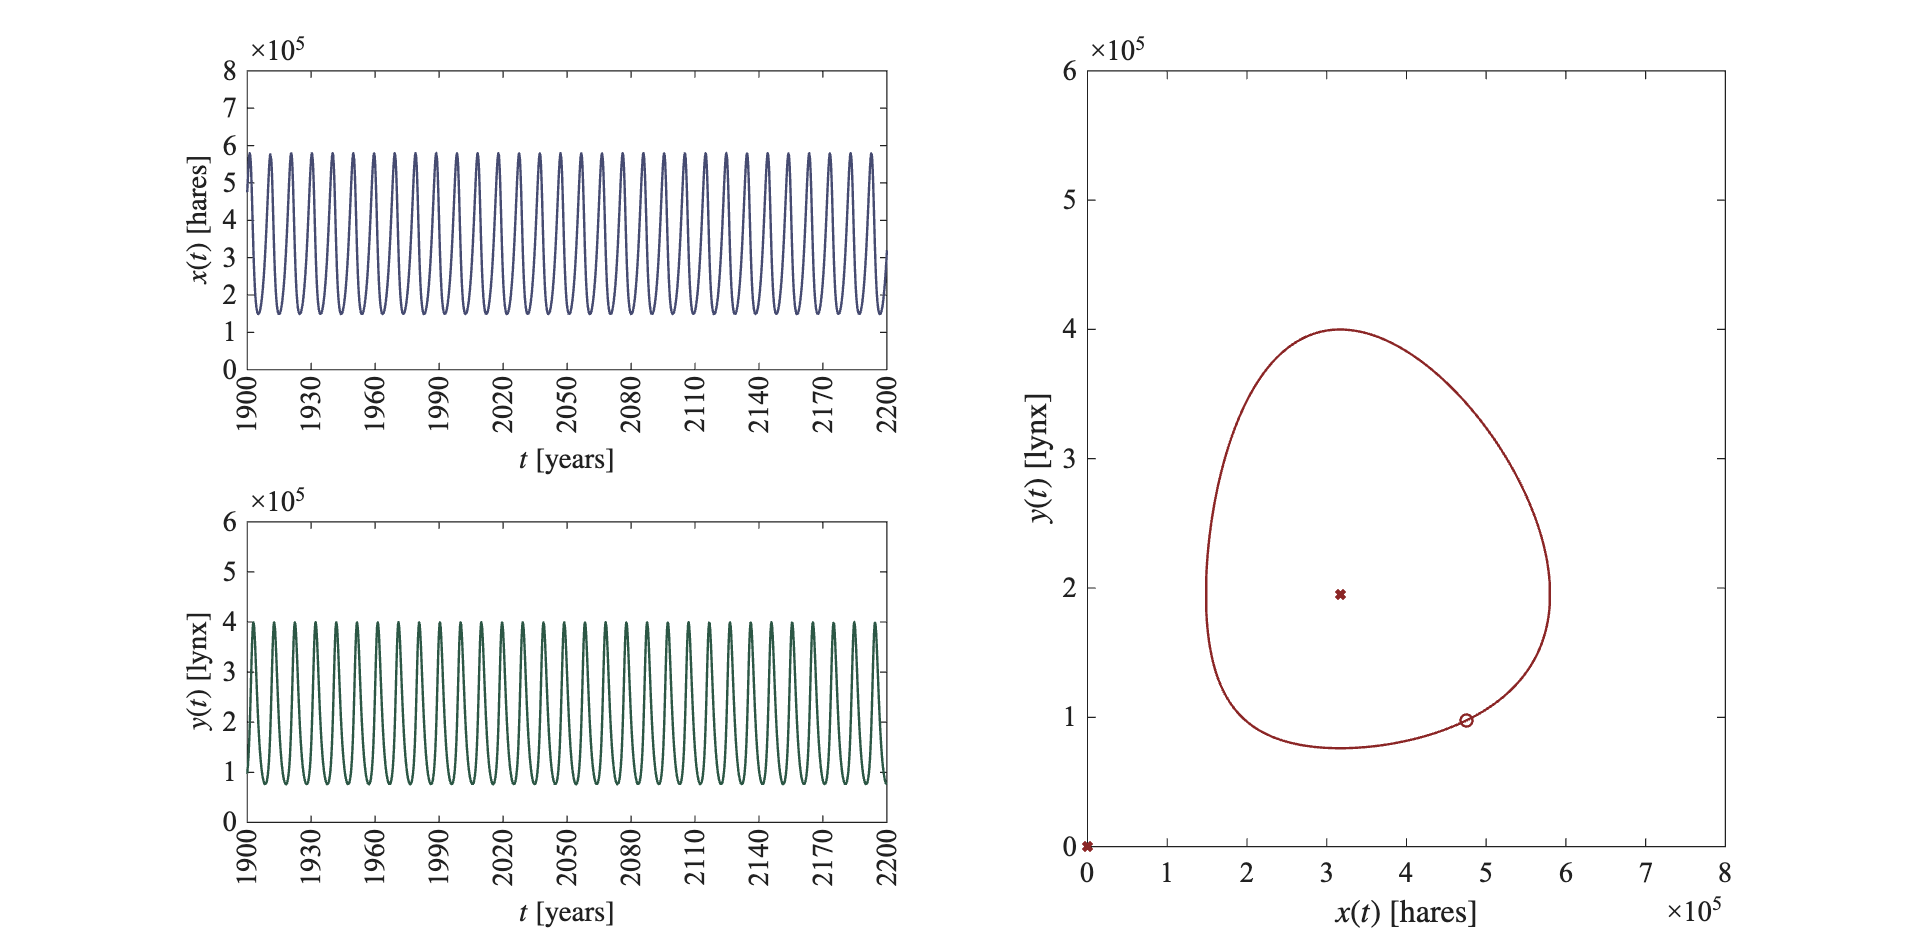

tend = 300;
xe0 = 0; ye0 = 0;
xe1 = gamma/delta; ye1 = alpha/beta;
[t,x,y] = LotkaVolterra([alpha,beta,delta,gamma],tend,1.5*xe1,0.5*ye1);
figname = 'eq_species_1.5xe-0.5ye';
plotphase(t,x,y,figname);...
    subplot(2,2,[2 4]); plot(xe0,ye0,'x','linewidth',2,'MarkerSize',5,'Color',clr3);...
    subplot(2,2,[2 4]); plot(xe1,ye1,'x','linewidth',2,'MarkerSize',5,'Color',clr3);...
    subplot(2,2,[2 4]); plot(1.5*xe1,0.5*ye1,'o','linewidth',1,'MarkerSize',5,'Color',clr3)

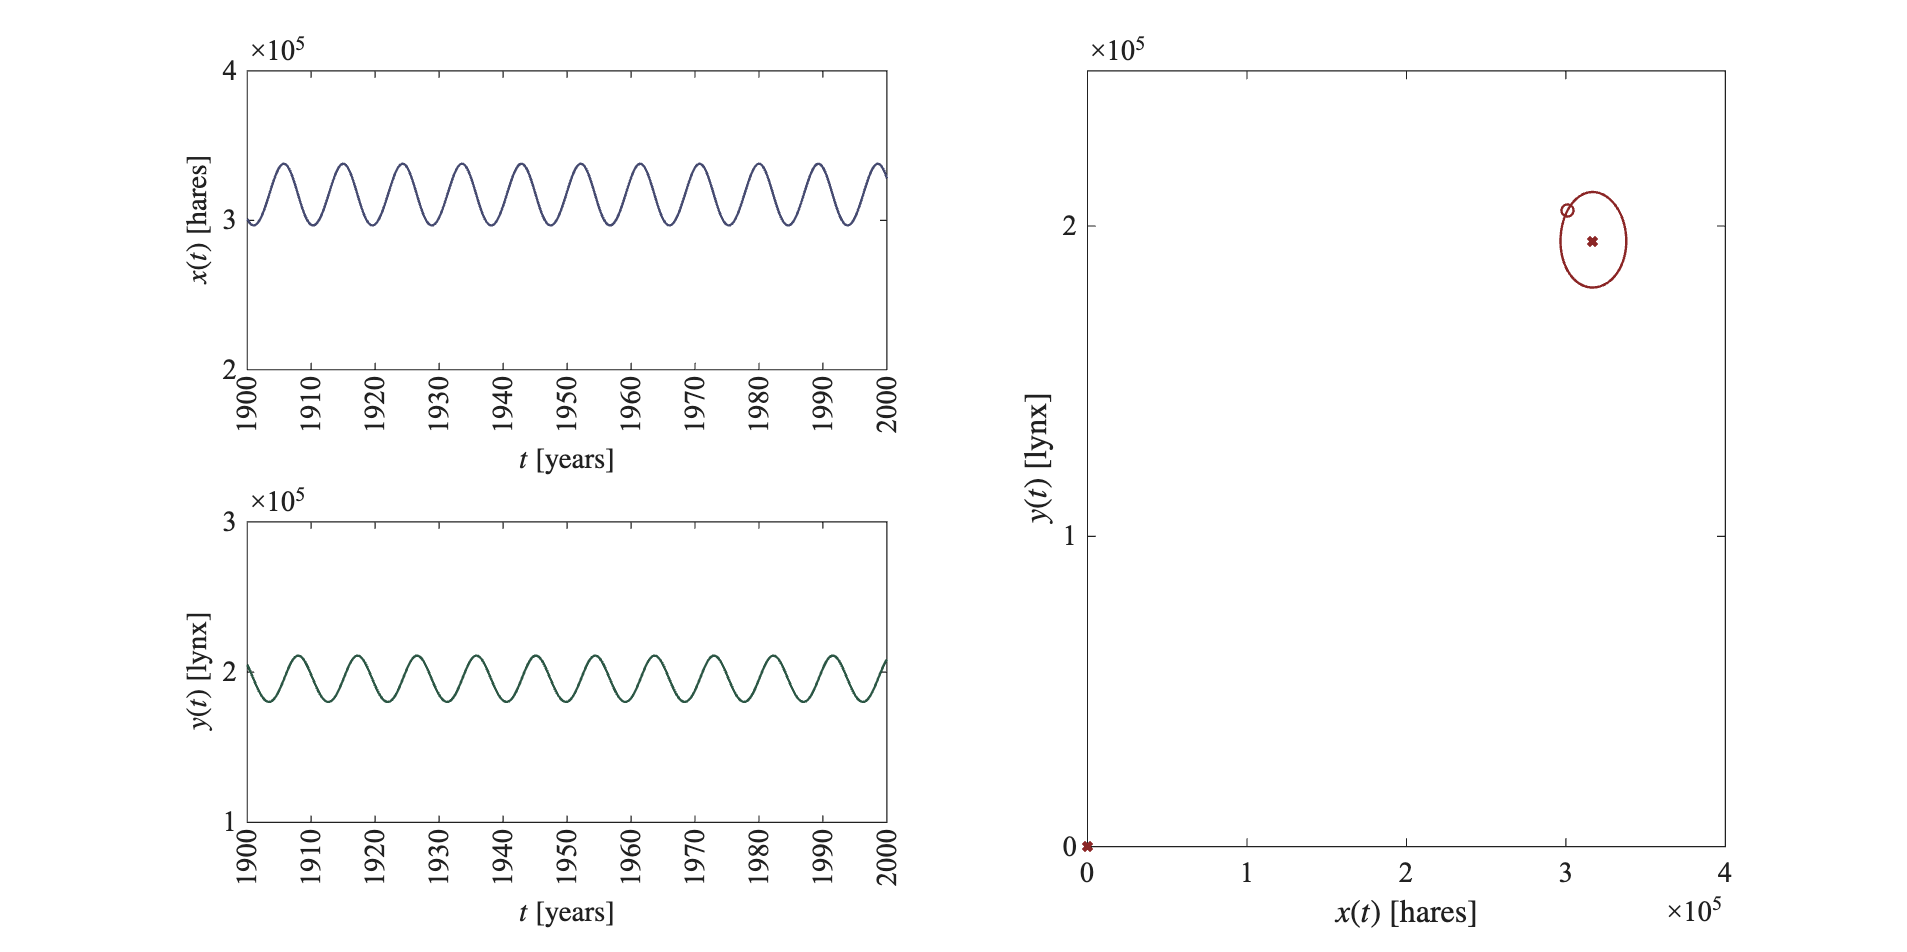

tend = 100;
xe0 = 0; ye0 = 0;
xe1 = gamma/delta; ye1 = alpha/beta;
[t,x,y] = LotkaVolterra([alpha,beta,delta,gamma],tend,0.95*xe1,1.05*ye1);
figname = 'eq_species_0.95xe-1.05ye';
plotphase(t,x,y,figname);...
    subplot(2,2,1); ylim([2E5 4E5]);...
    subplot(2,2,3); ylim([1E5 3E5]);...
    subplot(2,2,[2 4]); xlim([0 4E5]); ylim([0 2.5E5]);...
    subplot(2,2,[2 4]); plot(xe0,ye0,'x','linewidth',2,'MarkerSize',5,'Color',clr3);...
    subplot(2,2,[2 4]); plot(xe1,ye1,'x','linewidth',2,'MarkerSize',5,'Color',clr3);...
    subplot(2,2,[2 4]); plot(0.95*xe1,1.05*ye1,'o','linewidth',1,'MarkerSize',5,'Color',clr3)

## Funciones

function [to,xo,yo] = getdata(file,smooth,normalize)
    sys = readmatrix(file);
    to = round(sys(:,1));
    to = to - to(1); % t = [0 20] para el ajuste
    xo = sys(:,2)*1E4;
    yo = sys(:,3)*1E4;
        if smooth == false && normalize == false
            return
        elseif smooth == true && normalize == false
            xo = smoothdata(xo,'gaussian',5);
            yo = smoothdata(yo,'gaussian',5);
        elseif smooth == false && normalize == true
            xo = xo / max(xo);
            yo = yo / max(yo);
        elseif smooth == true && normalize == true
            xo = smoothdata(xo,'gaussian',5);
            yo = smoothdata(yo,'gaussian',5);
            xo = xo / max(xo);
            yo = yo / max(yo);
        end
end

function plotsys(t,x,y,figname,norm)
    set(figure(),'color','w')
    set(gcf,'units','centimeters','position',[1,1,20,15])
    fs = 12;
    clr1 = [70, 75, 113]/255;
    clr2 = [44, 87, 69]/255;
    
    subplot(2,1,1); hold on; box on; grid off;
    fontsize(fs,'points'); set(gca,'fontname','Times new Roman')
    plot(t+1900,x,'x','linewidth',1,'markersize',4,'Color',clr1)
    xlabel('$t$ [years]','Interpreter','latex')
    ylabel('$x(t)$ [hares]','Interpreter','latex')
    xlim([1900 1920]); xticks(1900:1:1920); xtickangle(90)
    if norm == true
        ylim([0 1.2]); yticks(0:0.2:1.2)
    elseif norm == false
        ylim([0 10]*1E5); yticks(0:2E5:10E5)
    end
    
    subplot(2,1,2); hold on; box on; grid off;
    fontsize(fs,'points'); set(gca,'fontname','Times new Roman')
    plot(t+1900,y,'x','linewidth',1,'markersize',4,'Color',clr2)
    xlabel('$t$ [years]','Interpreter','latex')
    ylabel('$y(t)$ [lynx]','Interpreter','latex')
    xlim([1900 1920]); xticks(1900:1:1920); xtickangle(90)
    if norm == true
        ylim([0 1.2]); yticks(0:0.2:1.2)
    elseif norm == false
        ylim([0 8]*1E5); yticks(0:2E5:8E5)
    end
    
    exportgraphics(gcf,[figname,'.pdf'],'ContentType','vector')
end

function mdl = fitmodel(to,xo,yo,p0,biostats)
    x0 = xo(1); y0 = yo(1);
    to = [to;to];
    fo = [xo;yo];
    
        function fa = model(p0,to)
            alpha = p0(1); beta = p0(2);
            delta = p0(3); gamma = p0(4);
            dt = 1e-2;
            time = (0:dt:max(to))';
            x = zeros(length(time),1); x(1) = x0;
            y = zeros(length(time),1); y(1) = y0;
            n =  round(max(to)/dt);
    
            for i = 1:n %Método de Heun (Euler mejorado)
                [fx,fy] = f(x(i),y(i));
                xn = x(i) + fx*dt;
                yn = y(i) + fy*dt;
                [fxn,fyn] = f(xn,yn);
                x(i+1) = x(i) + (fx + fxn)*dt/2;
                y(i+1) = y(i) + (fy + fyn)*dt/2;
            end
    
            function [dx,dy] = f(x,y)
                dx = alpha*x - beta*x*y;
                dy = delta*x*y - gamma*y;
            end
            ta = reshape(to,[],2);
            xa = interp1(time, x, ta(:,1), 'linear');
            ya = interp1(time, y, ta(:,1), 'linear');
            fa = [xa;ya];
        end
    
    mdl = fitnlm(to,fo,@model,p0);
    if biostats == true
        Estimate = table2array(mdl.Coefficients(:,1));
        SE = table2array(mdl.Coefficients(:,2));
        Pvalue = table2array(mdl.Coefficients(:,4));
        alfa = 0.05;
        CI95 = coefCI(mdl,alfa);
        dof = mdl.DFE;
        tval = tinv(1-alfa/2,dof);
        MoE = SE * tval;
        Parameters = {"alpha";"beta";"delta";"gamma"};
        R2a = mdl.Rsquared.Adjusted;
        RSS = mdl.SSE;
        AICc = mdl.ModelCriterion.AICc;
        Results = table(Parameters,Estimate,SE,MoE,CI95,Pvalue);
        fprintf('\n-----Biostadísticos-----')
        fprintf('\nCantidad de datos: %.f', numel(fo))
        fprintf('\nCantidad de parámetros: %.f', numel(Estimate))
        fprintf('\nGrados de libertad: %.f', dof)
        fprintf('\nValor t-student: %.3f', tval)
        fprintf('\nValor de significancia (alfa) para los intervalos de confianza: %.3f', alfa)
        fprintf('\nRelación n/k<40 para el cálculo del AICc: %.3f \n', numel(fo)/numel(Estimate))
        disp(Results)
        fprintf('\n-----Criterios de bondad de ajuste-----')
        fprintf('\nR cuadrada ajustada: %.3f', R2a)
        fprintf('\nSuma residual de cuadrados (RSS): %.3f', RSS)
        fprintf('\nCriterio de Información de Akaike corregido: %.3f', AICc)
    end
end

function plotfitting(t,x,y,ta,xa,ya,figname,norm)
    set(figure(),'color','w')
    set(gcf,'units','centimeters','position',[1,1,20,15])
    fs = 12;
    clr1 = [70, 75, 113]/255;
    clr2 = [44, 87, 69]/255;
    
    subplot(2,1,1); hold on; box on; grid off;
    fontsize(fs,'points'); set(gca,'fontname','Times new Roman')
    plot(t+1900,x,'x','linewidth',1,'markersize',4,'Color',clr1)
    
    plot(ta+1900,xa,'-','linewidth',1,'Color',clr2)
    
    xlabel('$t$ [years]','Interpreter','latex')
    ylabel('$x(t)$ [hares]','Interpreter','latex')
    xlim([1900 1920]); xticks(1900:1:1920); xtickangle(90)
    if norm == true
        ylim([0 1.2]); yticks(0:0.2:1.2)
    elseif norm == false
        ylim([0 10]*1E5); yticks(0:2E5:10E5)
    end
    
    subplot(2,1,2); hold on; box on; grid off;
    fontsize(fs,'points'); set(gca,'fontname','Times new Roman')
    plot(t+1900,y,'x','linewidth',1,'markersize',4,'Color',clr2)
    plot(ta+1900,ya,'-','linewidth',1,'Color',clr2)
    xlabel('$t$ [years]','Interpreter','latex')
    ylabel('$y(t)$ [lynx]','Interpreter','latex')
    xlim([1900 1920]); xticks(1900:1:1920); xtickangle(90)
    if norm == true
        ylim([0 1.2]); yticks(0:0.2:1.2)
    elseif norm == false
        ylim([0 8]*1E5); yticks(0:2E5:8E5)
    end
    
    exportgraphics(gcf,[figname,'.pdf'],'ContentType','vector')
end

function [time,x,y] = LotkaVolterra(p0,to,x0,y0)
    alpha = p0(1); beta = p0(2);
    delta = p0(3); gamma = p0(4);
    dt = 1e-2;
    time = (0:dt:max(to))';
    x = zeros(length(time),1); x(1) = x0;
    y = zeros(length(time),1); y(1) = y0;
    n = round(max(to)/dt);
    
    for i = 1:n %Método de Heun (Euler mejorado)
        [fx,fy] = f(x(i),y(i));
        xn = x(i) + fx*dt;
        yn = y(i) + fy*dt;
        [fxn,fyn] = f(xn,yn);
        x(i+1) = x(i) + (fx + fxn)*dt/2;
        y(i+1) = y(i) + (fy + fyn)*dt/2;
    end
    
    function [dx,dy] = f(x,y)
        dx = alpha*x - beta*x*y;
        dy = delta*x*y - gamma*y;
    end
end

function plotphase(t,x,y,figname)
    set(figure(),'color','w')
    set(gcf,'units','centimeters','position',[1,1,30,15])
    fs = 12;
    clr1 = [70, 75, 113]/255;
    clr2 = [44, 87, 69]/255;
    clr3 = [139, 38, 38]/255;

    subplot(2,2,1); hold on; box on; grid off;
    fontsize(fs,'points'); set(gca,'fontname','Times new Roman')
    plot(t+1900,x,'-','linewidth',1,'Color',clr1)
    xlabel('$t$ [years]','Interpreter','latex')
    ylabel('$x(t)$ [hares]','Interpreter','latex')
    xlim([1900 1900+max(t)]); xticks(1900:max(t)/10:1900+max(t)); xtickangle(90)
    ylim([0 8]*1E5); yticks(0:1E5:10E5)

    subplot(2,2,3); hold on; box on; grid off;
    fontsize(fs,'points'); set(gca,'fontname','Times new Roman')
    plot(t+1900,y,'-','linewidth',1,'Color',clr2)
    xlabel('$t$ [years]','Interpreter','latex')
    ylabel('$y(t)$ [lynx]','Interpreter','latex')
    xlim([1900 1900+max(t)]); xticks(1900:max(t)/10:1900+max(t)); xtickangle(90)
    ylim([0 6]*1E5); yticks(0:1E5:8E5)

    subplot(2,2,[2 4]); hold on; box on; grid off;
    fontsize(fs,'points'); set(gca,'fontname','Times new Roman')
    plot(x,y,'-','linewidth',1,'Color',clr3)
    xlabel('$x(t)$ [hares]','Interpreter','latex')
    ylabel('$y(t)$ [lynx]','Interpreter','latex')
    xlim([0 8]*1E5); xticks(0:1E5:10E5)
    ylim([0 6]*1E5); yticks(0:1E5:8E5)

    exportgraphics(gcf,[figname,'.pdf'],'ContentType','vector')
end